## Setup data

clc 
clear
table = readtable('Data\KalmanIkkeStille.txt');

sync = table.Var1;

IL=table(ismember(table.Var1,'IL'),:);
IL_Data = IL{:,{'Var2','Var3','Var4','Var5','Var6','Var7'}};


ML=table(ismember(table.Var1,'ML'),:);
ML_Data = ML{:,{'Var2','Var3','Var4','Var5','Var6','Var7','Var8','Var9','Var10','Var11'}};

y_meas = [ML_Data(:,8), ML_Data(:,9), ML_Data(:,10),ML_Data(:,7),ML_Data(:,1),ML_Data(:,2),ML_Data(:,3)].';
u_in = [IL_Data(:,1:3) IL_Data(:,4:6)].';
x_compare = [ML_Data(:,1),ML_Data(:,2),ML_Data(:,3),ML_Data(:,4),ML_Data(:,5),ML_Data(:,6)].';
n = size(IL,1);
m = size(ML,1);

save("Data/Kalman_Data.mat","sync","n","m","y_meas","u_in","x_compare")

## Complementary filter

clc
clear
load("Data\Kalman_Data.mat")
T1 = linspace(0,n/400,n);
T2 = linspace(0,n/400,m);
Be = [-212.3951, 6.2007, -510.1044].';
offset = 90*pi/180;

theta = atan2(u_in(3,:),-u_in(2,:)) - offset

theta =     0.0005   -0.0010   -0.0020   -0.0005   -0.0005    0.0010    0.0005   -0.0005   -0.0015         0    0.0005    0.0005    0.0005   -0.0010    0.0010   -0.0015   -0.0010    0.0005    0.0005   -0.0005    0.0020    0.0010    0.0010   -0.0005   -0.0005    0.0005         0   -0.0010   -0.0015   -0.0005   -0.0015   -0.0005   -0.0020   -0.0020   -0.0010   -0.0005   -0.0015   -0.0005   -0.0010   -0.0010   -0.0015   -0.0010   -0.0015         0         0   -0.0015   -0.0005    0.0005   -0.0005   -0.0005


phi = atan2(u_in(3,:),u_in(1,:)) - offset

phi =    -0.0237   -0.0233   -0.0233   -0.0233   -0.0228   -0.0233   -0.0238   -0.0228   -0.0223   -0.0228   -0.0243   -0.0228   -0.0233   -0.0228   -0.0233   -0.0223   -0.0233   -0.0223   -0.0218   -0.0223   -0.0228   -0.0223   -0.0243   -0.0238   -0.0243   -0.0243   -0.0218   -0.0223   -0.0223   -0.0243   -0.0238   -0.0253   -0.0238   -0.0243   -0.0257   -0.0243   -0.0253   -0.0243   -0.0238   -0.0238   -0.0243   -0.0233   -0.0248   -0.0233   -0.0243   -0.0238   -0.0253   -0.0243   -0.0243   -0.0248


psi = atan2(Be(2), Be(1)) - atan2(y_meas(2,:),y_meas(1,:))

psi =     0.0081    0.0081    0.0082    0.0087    0.0026   -0.0086   -0.0086   -0.0109   -0.0046   -0.0109   -0.0042   -0.0042   -0.0033   -0.0113    0.0036    0.0087    0.0087    0.0020    0.0084    0.0079    0.0091    0.0091    0.0088    0.0087    0.0017   -0.0089   -0.0089   -0.0117   -0.0043   -0.0113   -0.0109   -0.0109   -0.0038   -0.0042   -0.0117   -0.0043   -0.0043   -0.0121   -0.0088   -0.0184   -0.0117   -0.0117   -0.0109   -0.0039   -0.0048    0.0080    0.0080    0.0092    0.0085    0.0076



for i=2:m
    if (abs(psi(i)-psi(i-1)) > pi)
        i;
        psi(i) = psi(i) - 2*pi;
    end
end

T = 1/400

T = 0.0025

Ts = 1/50

Ts = 0.0200

tau = 0.25

tau = 0.2500

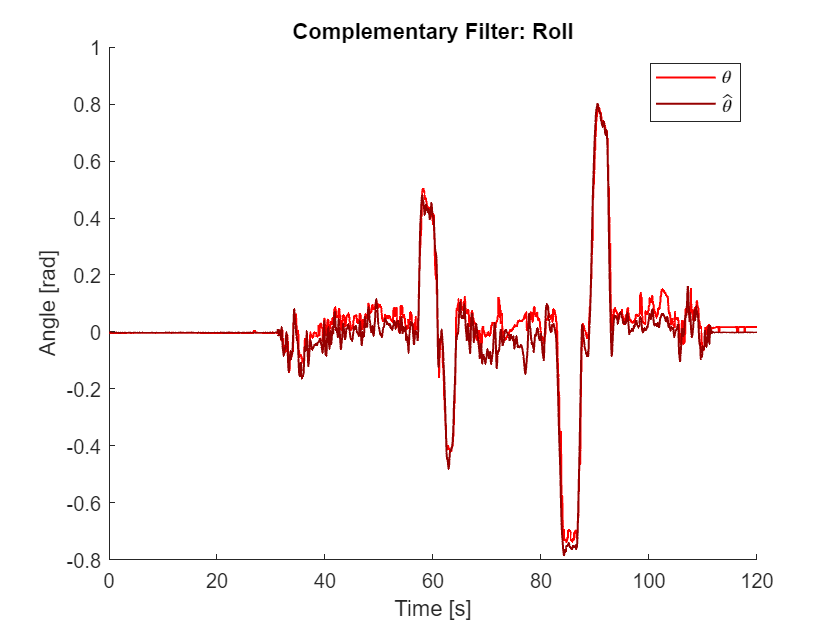

theta_c = zeros(1,n);
phi_c = zeros(1,n);
psi_c = zeros(1,m);
psi_gyro = zeros(1,m);

error = zeros(6,m);

j = 2;
for i=2:n
    theta_c(i) = T/(T+2*tau) * (tau*u_in(4,i)+theta(i)) + T/(T+2*tau) * (tau*u_in(4,i-1)+theta(i-1)) - (T-2*tau)/(T+2*tau)*theta_c(i-1);
    phi_c(i) = T/(T+2*tau) * (tau*u_in(5,i)+phi(i)) + T/(T+2*tau) * (tau*u_in(5,i-1)+phi(i-1)) - (T-2*tau)/(T+2*tau)*phi_c(i-1);
    
    compare = (sync{i+j}(end-1) == 'ML');
    if(compare(1))
        psi_gyro(j) = psi_gyro(j)/8;
        psi_c(j) = Ts/(Ts+2*tau) * (tau*psi_gyro(j)+psi(j)) + Ts/(Ts+2*tau) * (tau*psi_gyro(j-1)+psi(j-1)) - (Ts-2*tau)/(Ts+2*tau)*psi_c(j-1);
        error(1:3,j) = [theta_c(i) - x_compare(4,j); phi_c(i) - x_compare(5,j); psi_c(j) - x_compare(6,j)];
        j = j + 1;
    else
        psi_gyro(j) = psi_gyro(j) + u_in(6,i);
    end
    
end


figure()
hold on
plot(T2,x_compare(4,1:m),color=[1,0,0],LineWidth=1)
plot(T1,theta_c,color=[150/255,0,0],LineWidth=1)
title("Complementary Filter: Roll")
ylabel("Angle [rad]")
xlabel("Time [s]")
xlim([0,120])
legend(["$\theta$","$\hat{\theta}$"],Interpreter="latex")
hold off
saveas(gcf,'Images/Comp_Roll','epsc')

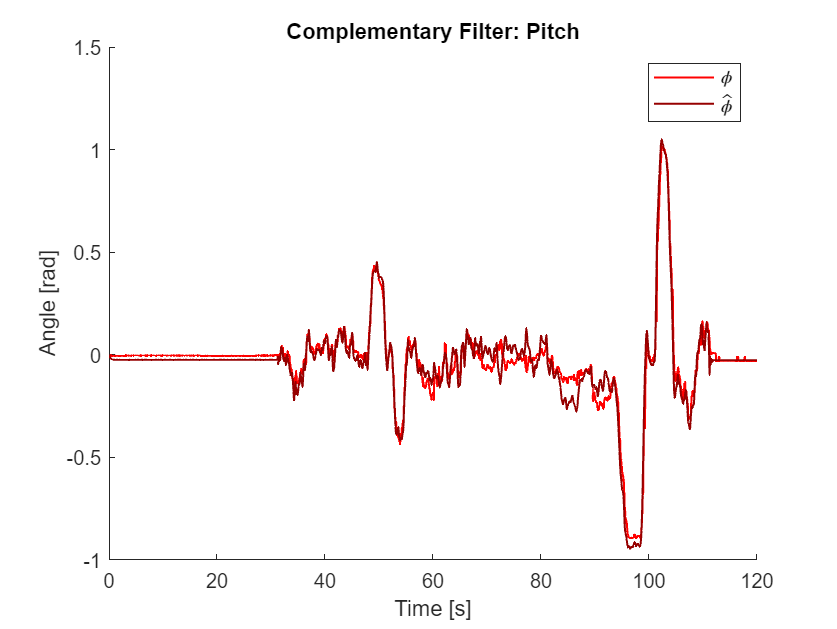


figure()
hold on
plot(T2,x_compare(5,1:m),color=[1,0,0],LineWidth=1)
plot(T1,phi_c,color=[150/255,0,0],LineWidth=1)
title("Complementary Filter: Pitch")
ylabel("Angle [rad]")
xlabel("Time [s]")
xlim([0,120])
legend(["$\phi$","$\hat{\phi}$"],Interpreter="latex")
hold off
saveas(gcf,'Images/Comp_Pitch','epsc')

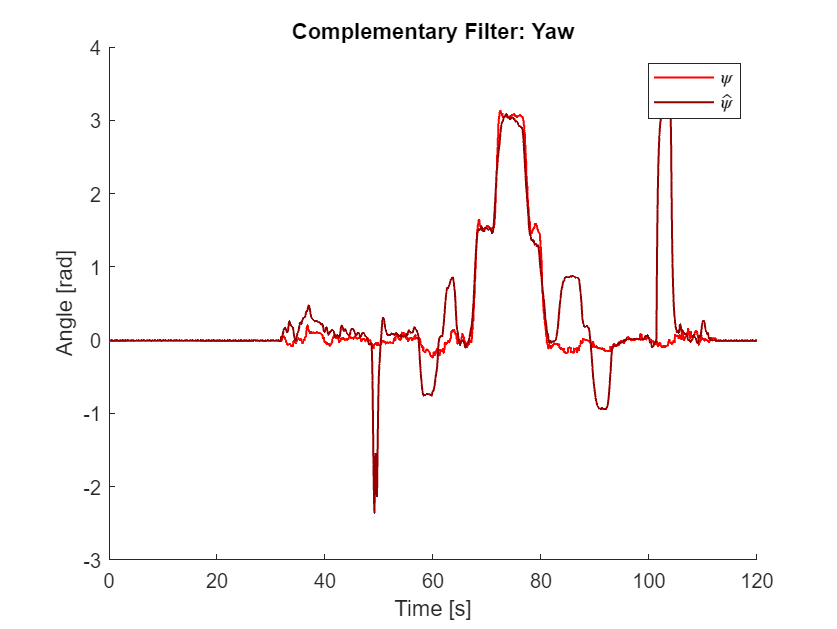


figure()
hold on
plot(T2,x_compare(6,1:m),color=[1,0,0],LineWidth=1)
plot(T2,psi_c,color=[150/255,0,0],LineWidth=1)
title("Complementary Filter: Yaw")
ylabel("Angle [rad]")
xlabel("Time [s]")
xlim([0,120])
legend(["$\psi$","$\hat{\psi}$"],Interpreter="latex")
hold off
saveas(gcf,'Images/Comp_Yaw','epsc')

## Kalman filter


Ts = 1/400;
Ts2 = 1/50;
Be = [-212.3951, 6.2007, -510.1044].';

R_translate =@(theta,phi,psi) [cos(phi)*cos(psi), cos(phi)*sin(psi), -sin(phi); cos(psi)*sin(phi)*sin(theta) - cos(theta)*sin(psi), cos(psi)*cos(theta) + sin(phi)*sin(psi)*sin(theta), cos(phi)*sin(theta); sin(psi)*sin(theta) + cos(psi)*cos(theta)*sin(phi), cos(theta)*sin(phi)*sin(psi) - cos(psi)*sin(theta), cos(phi)*cos(theta)];
R =@(ang) R_translate(ang(1),ang(2),ang(3));

T_translate =@(theta,phi,psi) [1 0 -sin(phi); 0 cos(theta) cos(phi)*sin(theta); 0 -sin(theta) cos(phi)*cos(theta)];
T =@(ang) T_translate(ang(1),ang(2),ang(3));
T_inv=@(ang) [1     tan(ang(2))*sin(ang(1))     tan(ang(2))*cos(ang(1));
              0     cos(ang(1))                 -sin(ang(1));
              0     sin(ang(1))/cos(ang(2))     cos(ang(1))/cos(ang(2))];

Additive noise

f = @(x,u,w) [
     x(1:3) + Ts*x(4:6) + (Ts^2)/2*(R(x(7:9)).'*(u(1:3)-x(13:15)) - [0;0;9.82]) + (Ts^2)/2*w(1:3);
     x(4:6) + Ts*(R(x(7:9)).'*(u(1:3)-x(13:15)) - [0;0;9.82]) + Ts*w(1:3);
     x(7:9) + Ts*R(x(7:9)).'*(u(4:6)-x(16:18)) + Ts*w(4:6);
     R(x(7:9)).'*(u(4:6)-x(16:18)) + w(4:6);
     x(13:15) + w(7:9);
     x(16:18) + w(10:12);
    ];

syms x1 x2 x3 x4 x5 x6 x7 x8 x9 x10 x11 x12 x13 x14 x15 x16 x17 x18 
syms u1 u2 u3 u4 u5 u6
syms w1 w2 w3 w4 w5 w6 w7 w8 w9 w10 w11 w12
syms v1 v2 v3 v4 v5 v6 v7
X = [x1 x2 x3 x4 x5 x6 x7 x8 x9 x10 x11 x12 x13 x14 x15 x16 x17 x18].';
U = [u1 u2 u3 u4 u5 u6].';
W = [w1 w2 w3 w4 w5 w6 w7 w8 w9 w10 w11 w12].';
V = [v1 v2 v3 v4 v5 v6 v7].';

F =@(x,u,w) jacobian(f(x,u,w),x);
matlabFunction(F(X,U,W),'File','F_JACOBIAN_idiot.m','Vars',[X.',U.',W.']);

F_JACOBIAN =@(x,u,w) F_JACOBIAN_idiot(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9),x(10),x(11),x(12),x(13),x(14),x(15),x(16),x(17),x(18), ...
                                u(1),u(2),u(3),u(4),u(5),u(6), ...
                                w(1),w(2),w(3),w(4),w(5),w(6),w(7),w(8),w(9),w(10),w(11),w(12));
h =@(x,v) [
    R(x(7:9))*(Be)+v(1:3);
    x(3)+v(4);
    x(1:3) + v(5:7)
    ];

H =@(x,v) jacobian(h(x,v),x);
matlabFunction(H(X,V),'File','H_JACOBIAN_idiot.m','Vars',[X.',V.']);

H_JACOBIAN =@(x,v) H_JACOBIAN_idiot(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8),x(9),x(10),x(11),x(12),x(13),x(14),x(15),x(16),x(17),x(18), ...
                                    v(1),v(2),v(3),v(4),v(5),v(6),v(7));

load("Data/Kalman_Data.mat")

%initialise
sigma_acc = diag([0.5974, 0.6488, 0.9057]*1e-4);
sigma_gyro = diag([0.0089, 0.0100, 0.0076]*1e-4);
sigma_acc_bias = diag([0.001, 0.001, 0.001]*1e-7);
sigma_gyro_bias = diag([0.001, 0.001, 0.001]*1e-7);
sigma_IMU = diag([diag(sigma_acc); diag(sigma_gyro); diag(sigma_acc_bias); diag(sigma_gyro_bias)]);
E = [eye(3) zeros(3,9); eye(3) zeros(3,9); zeros(3) eye(3) zeros(3,6); zeros(3) eye(3) zeros(3,6); zeros(3,6) eye(3) zeros(3); zeros(3,9) eye(3)];

sigma_meas = diag([13.8660, 3.2265, 5.7432, 0.1211,0.0813e-8, 0.0633e-8, 0.2189e-8]);
R_k = sigma_meas;

NoStates = 18;
NoMeas = 7;
x_est = zeros(NoStates,n);
x_pred = zeros(NoStates,n);
y_pred = zeros(NoMeas,m);
y_err = zeros(NoMeas,m);
Pk_est = zeros(NoStates,NoStates,m);
Pk_pred = zeros(NoStates,NoStates,m);
K = zeros(NoStates,NoMeas,m);
Pk_plot = zeros(NoStates,m);
w_k = mvnrnd(zeros(12,1),Ts*sqrt(sigma_IMU), n).';
v_k = mvnrnd(zeros(7,1),Ts2*sqrt(sigma_meas), m).';
Pk_est(:,:,1) = 0.1*eye(NoStates);

j = 1;

prog = waitbar(0, 'Starting');
for i = 2:n
    % Time update
    x_pred(:,i) = f(x_est(:,i-1),u_in(:,i),w_k(:,j));
    F_kt =  F_JACOBIAN(x_est(:,i-1),u_in(:,i),w_k(:,j));
    Pk_pred(:,:,i) = F_kt*Pk_est(:,:,i-1)*F_kt.' + E*sigma_IMU*E.';
    
    compare = (sync{i+j}(end-1) == 'ML');
    if(compare(1))
        %Measurment update
        y_pred(:,j) = h(x_pred(:,i),v_k(:,j));
        H_kt = H_JACOBIAN(x_pred(:,i),v_k(:,j));
    
        y_err(:,j) = y_meas(:,j) - y_pred(:,j);
        
        K(:,:,j) = Pk_pred(:,:,i) * H_kt.'/(H_kt*Pk_pred(:,:,i)*H_kt.'+R_k);
        
        x_est(:,i) = x_pred(:,i) + K(:,:,j)*y_err(:,j);
        Pk_est(:,:,i) = (eye(NoStates)-K(:,:,j)*H_kt)*Pk_pred(:,:,i)*(eye(NoStates)-K(:,:,j)*H_kt).'+ K(:,:,j)*R_k*K(:,:,j).';
        Pk_plot(:,i) = diag(Pk_est(:,:,i));

        error(4:6,j) = [x_est(7:9,i)-x_compare(4:6,j)];

        j = j + 1;
    else
        x_est(:,i) = x_pred(:,i);
        Pk_est(:,:,i) = Pk_pred(:,:,i);
        Pk_plot(:,i) = diag(Pk_est(:,:,i));
    end


    waitbar(i/n, prog, sprintf('Progress: %d %%', floor(i/n*100)));
end
close(prog)

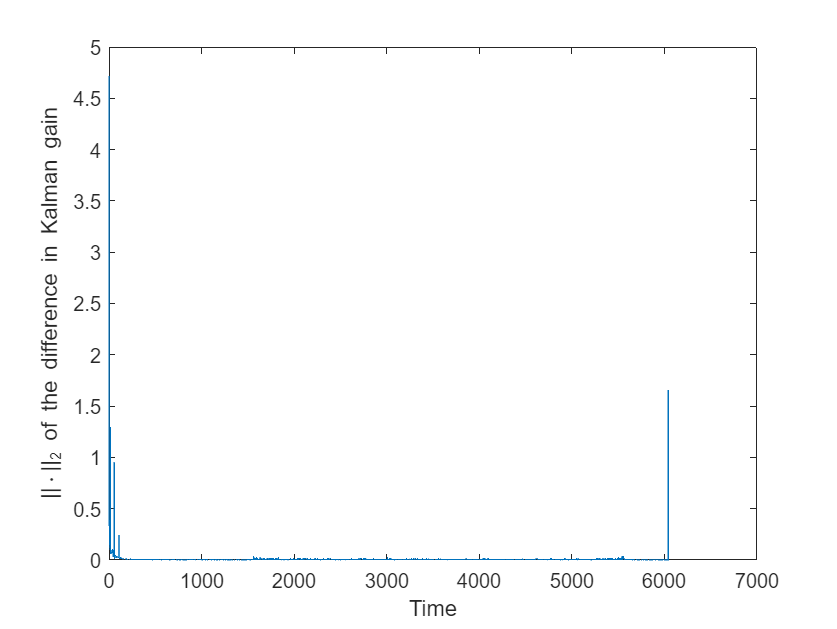

T1 = linspace(0,n/400,n);
T2 = linspace(0,n/400,m);

Difference=zeros(1,m-1);
for k=1:m-1 
    Difference(1,k)=norm(K(:,:,k+1)-K(:,:,k),2);
end 
figure()
plot(Difference)
xlabel("Time")
ylabel("||\cdot||_2 of the difference in Kalman gain")

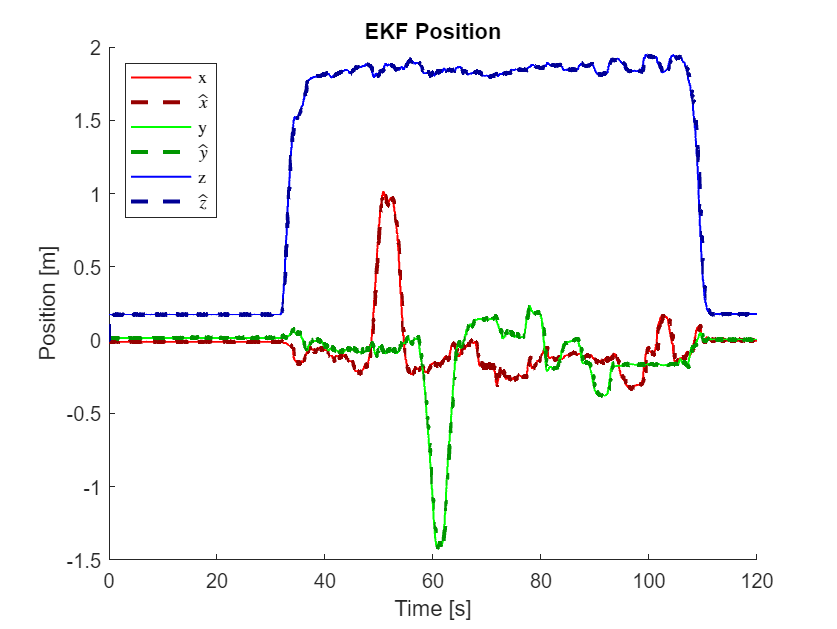


figure()
hold on
plot(T2,x_compare(1,1:m),color=[1,0,0],LineWidth=1)
plot(T1,x_est(1,:),color=[150/255,0,0],LineStyle='--',LineWidth=2)
plot(T2,x_compare(2,1:m),color=[0,1,0],LineWidth=1)
plot(T1,x_est(2,:),color=[0,150/255,0],LineStyle='--',LineWidth=2)
plot(T2,x_compare(3,1:m),color=[0,0,1],LineWidth=1)
plot(T1,x_est(3,:),color=[0,0,150/255],LineStyle='--',LineWidth=2)
ylabel("Position [m]")
xlabel("Time [s]")
xlim([0,120])
legend(["x","$\hat{x}$","y","$\hat{y}$","z","$\hat{z}$"],Interpreter="latex",Location="northwest")
title("EKF Position")
hold off
saveas(gcf,'Images/EKF_Pos','epsc')

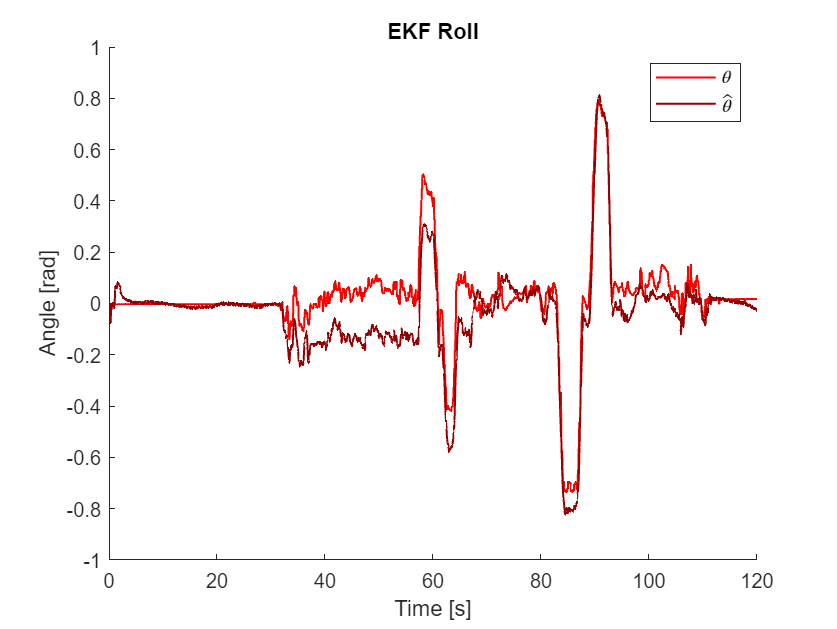



figure()
hold on
plot(T2,x_compare(4,1:m),color=[1,0,0],LineWidth=1)
plot(T1,x_est(7,:),color=[150/255,0,0],LineWidth=1)
title("EKF Roll")
ylabel("Angle [rad]")
xlabel("Time [s]")
xlim([0,120])
legend(["$\theta$","$\hat{\theta}$"],Interpreter="latex")
hold off
saveas(gcf,'Images/EKF_Roll','epsc')

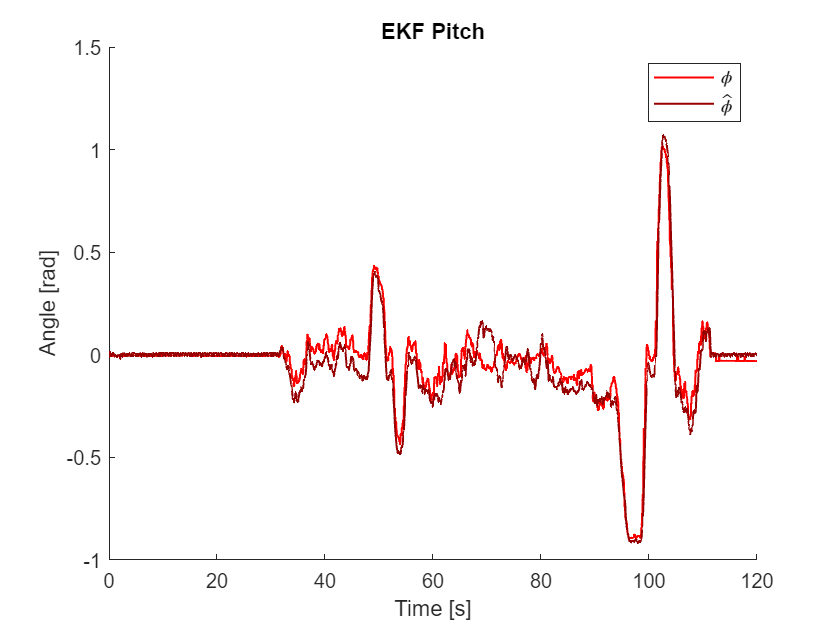


figure()
hold on
plot(T2,x_compare(5,1:m),color=[1,0,0],LineWidth=1)
plot(T1,x_est(8,:),color=[150/255,0,0],LineWidth=1)
title("EKF Pitch")
ylabel("Angle [rad]")
xlabel("Time [s]")
xlim([0,120])
legend(["$\phi$","$\hat{\phi}$"],Interpreter="latex")
hold off
saveas(gcf,'Images/EKF_Pitch','epsc')

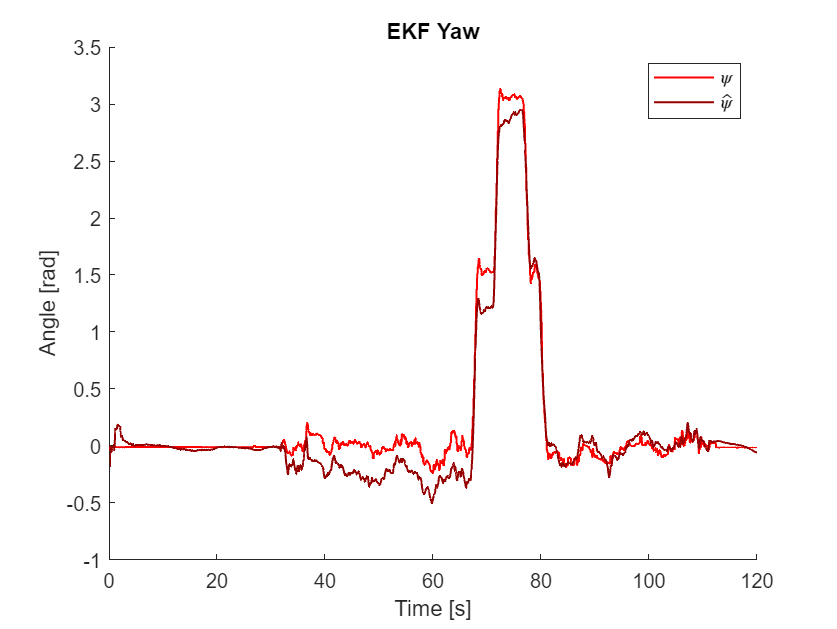


figure()
hold on
plot(T2,x_compare(6,1:m),color=[1,0,0],LineWidth=1)
plot(T1,x_est(9,:),color=[150/255,0,0],LineWidth=1)
title("EKF Yaw")
ylabel("Angle [rad]")
xlabel("Time [s]")
xlim([0,120])
legend(["$\psi$","$\hat{\psi}$"],Interpreter="latex")
hold off
saveas(gcf,'Images/EKF_Yaw','epsc')

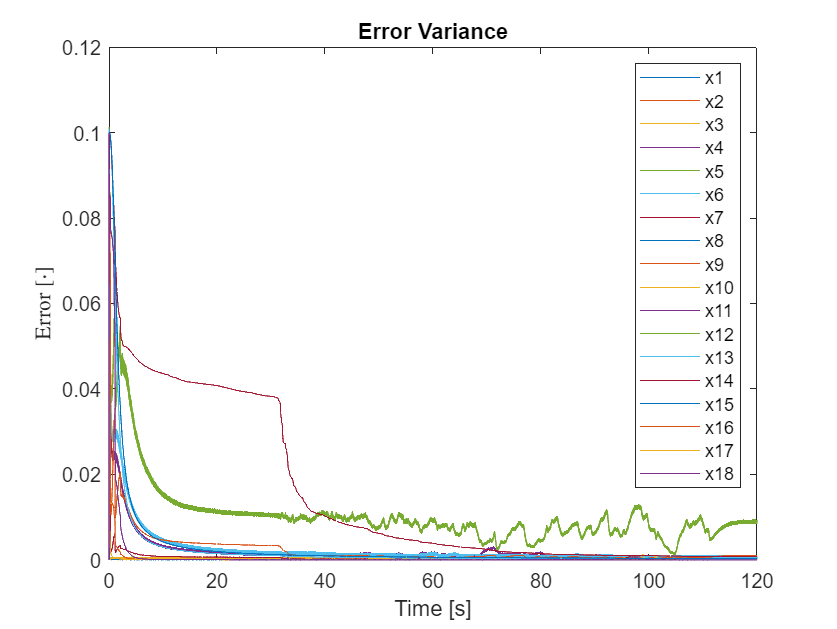


figure()
plot(T1,Pk_plot.')
title("Error Variance")
ylabel("Error $[\cdot]$",Interpreter="latex")
xlabel("Time [s]")
xlim([0,120])
legendCell = string(X(1:NoStates));
legend(legendCell)
saveas(gcf,'Images/EKF_error_covariance','epsc')

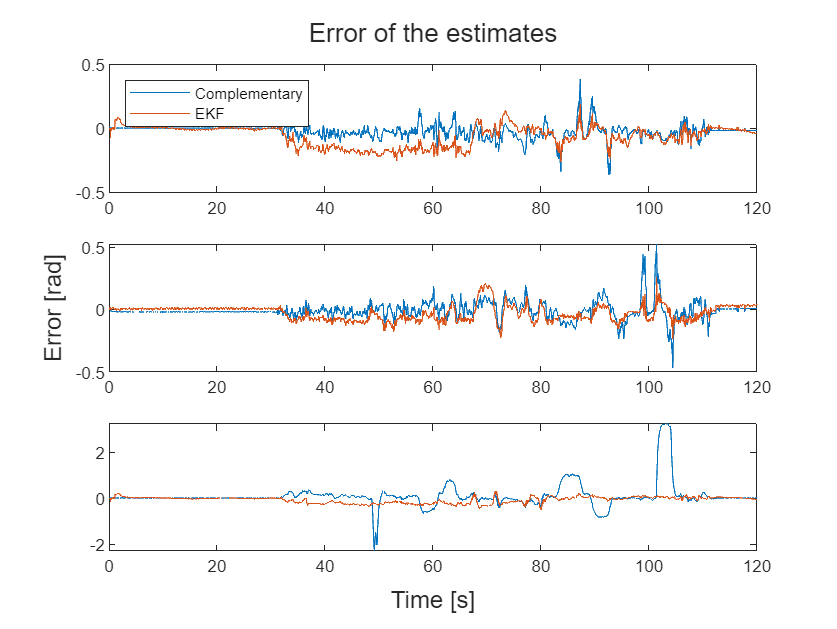

figure()
f=tiledlayout('vertical');
nexttile
plot(T2,error(1,:),T2,error(4,:))
legend(["Complementary", "EKF"], Location="northwest")
xlim([0,120])
nexttile
plot(T2,error(2,:),T2,error(5,:))
xlim([0,120])
nexttile
plot(T2,error(3,:),T2,error(6,:))
xlim([0,120])
title(f, "Error of the estimates")
xlabel(f,'Time [s]')
ylabel(f,'Error [rad]')


mean((error.').^2)

ans =     0.0036    0.0051    0.3028    0.0098    0.0046    0.0229
